# Planar RRP

l1=1

l1 = 1

l2 =1

l2 = 1


DH.theta = [0 0 0];
DH.d = [0 0 0];
DH.a = [l1 0 0];
DH.alpha = [0 pi/2 0];
DH.type = [0 0 1];
DH.offset = [0 pi/2 l2];

struct2table(DH,"AsArray",true)

ans = 1×10 table
    a1    a2    d1    d2        theta            d              a                 alpha               type               offset        
    __    __    __    ___    ___________    ___________    ___________    _____________________    ___________    _____________________

    1     1     0     0.5    0    0    0    0    0    0    1    1    1    0    1.5708         0    0    0    1    0    1.5708         1


qlim = [-pi pi;-pi pi; 0 1];
name = 'RRP_planar';

RRP_planar = create_robot_from_DH(DH,qlim,name)

 
RRP_planar = 
 
RRP_planar:: 3 axis, RRP, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|          1|
+---+-----------+-----------+-----------+-----------+-----------+
 


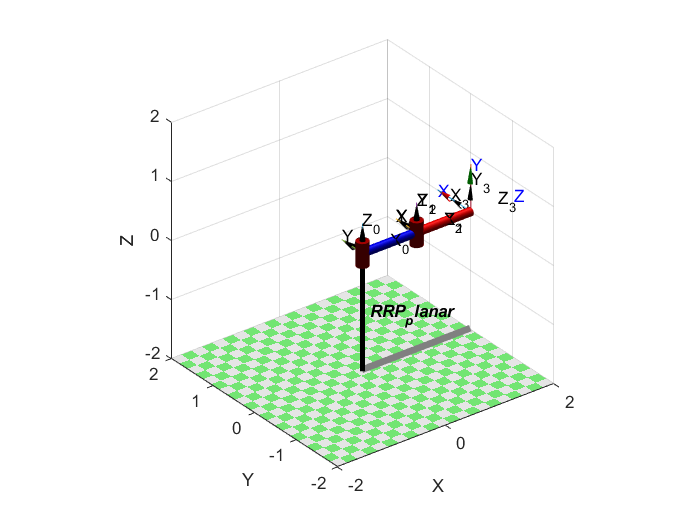

visualize_DH(RRP_planar)

set(gcf,'Visible','on')

### Forward Kinematic

q = sym('q',[1 3])

$$q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

Ai = @(theta,d,a,alpha) (trotz(theta)*transl([0 0 d])*transl([a 0 0])*trotx(alpha) ); % inline function that compute the homogeneous transformation due to the DH convention

A1 = Ai(q(1),0,DH.a(1),DH.alpha(1))

$$A1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = Ai(q(2)+pi/2,0,DH.a(2),DH.alpha(2))

$$A2 = \left(\begin{array}{cccc} \cos\left(q_{2}+\frac{\pi }{2}\right) & 0 & \sin\left(q_{2}+\frac{\pi }{2}\right) & 0\\ \sin\left(q_{2}+\frac{\pi }{2}\right) & 0 & -\cos\left(q_{2}+\frac{\pi }{2}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = Ai(0,q(3)+DH.offset(3),DH.a(3),DH.alpha(3))

$$A3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}+1\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T=simplify(A1*A2*A3)

$$T = \left(\begin{array}{cccc} -\sin\left(q_{1}+q_{2}\right) & 0 & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)+q_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right) & 0 & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}+q_{2}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

end effector pose:$\bar{x_e} = k(\ \bar{q}\ )$

xe = [T(1:2,4); sum(q(1:2))]

$$xe = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)+q_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)+q_{3}\,\sin\left(q_{1}+q_{2}\right)\\ q_{1}+q_{2} \end{array}\right)$$

wich can be compared with the one of the RRR planar


$$\left(\begin{array}{c}
\cos \left(\theta_1 +\theta_2 +\theta_3 \right)+\cos \left(\theta_1 +\theta_2 \right)+\cos \left(\theta_1 \right)\\
\sin \left(\theta_1 +\theta_2 +\theta_3 \right)+\sin \left(\theta_1 +\theta_2 \right)+\sin \left(\theta_1 \right)\\
\theta_1 +\theta_2 +\theta_3 
\end{array}\right)$$
